syms h(x)


t = 0:10000;
h(x) = 98*exp(-x/(172800))

$$h(x) = 98\,{\mathrm{e}}^{-\frac{x}{172800}}$$


HReal = double(h(t)) + 0.01*rand(1, length(t));
HFiltered = zeros(1, length(HReal));

alpha = 0.01

alpha = 0.0100

HFiltered(1) = HReal(1);

for i = 2:length(t)
    HFiltered(i) = HFiltered(i - 1) + alpha * (HReal(i) - HFiltered(i - 1));
end

dHReal = diff(HFiltered);
dHFiltered = zeros(1, length(dHReal));
dHFiltered(1) = dHReal(1);

for i = 2:length(dHFiltered)
    dHFiltered(i) = dHFiltered(i - 1) + alpha * (dHReal(i) - dHFiltered(i - 1));
end

hp = diff(h)

$$hp(x) = -\frac{49\,{\mathrm{e}}^{-\frac{x}{172800}}}{86400}$$

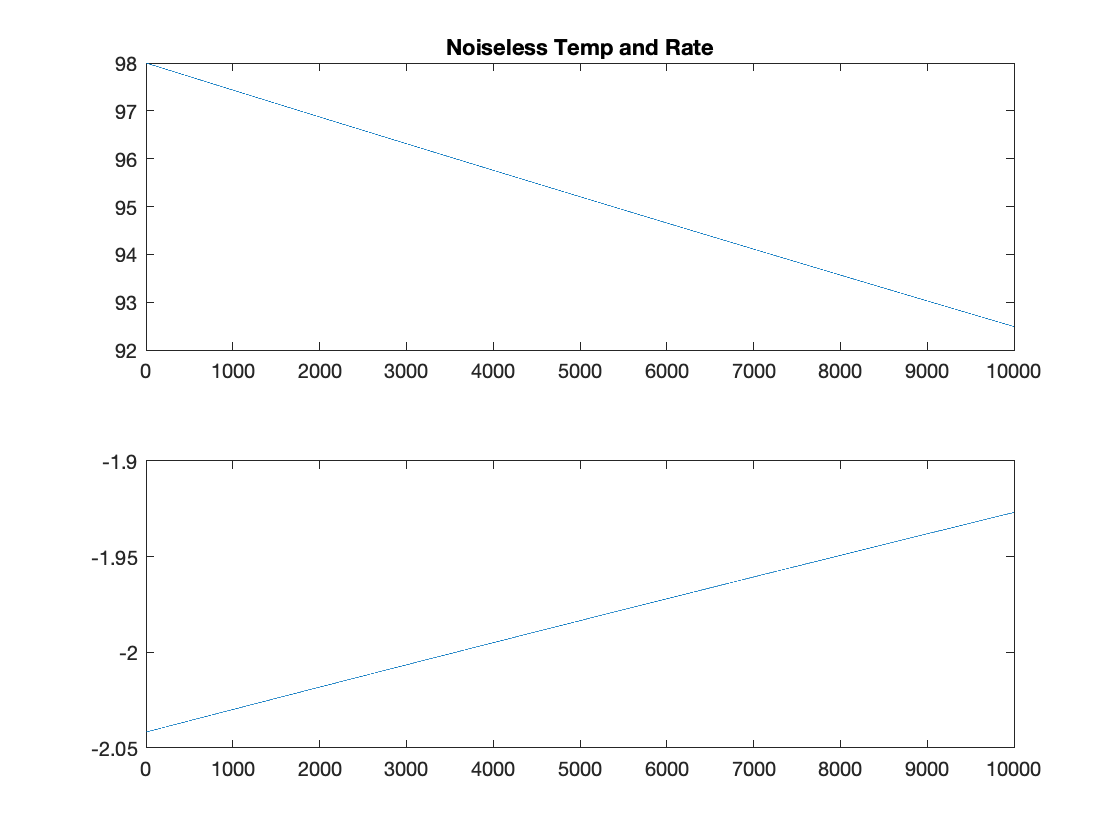

subplot 211
plot(t,h(t))
title('Noiseless Temp and Rate')
subplot 212
plot(t, 3600*hp(t))

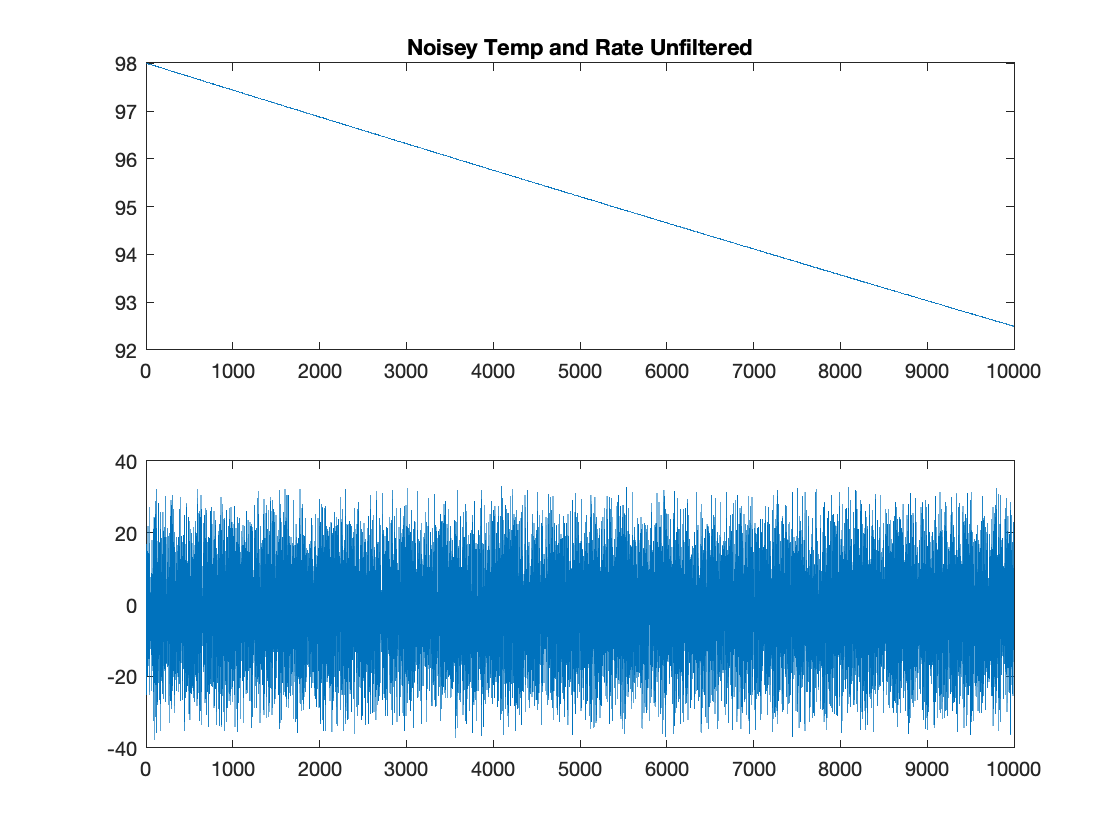


figure
subplot 211
plot(t, HReal)
title('Noisey Temp and Rate Unfiltered')
subplot 212
plot(t(1:end-1), 3600*diff(HReal))

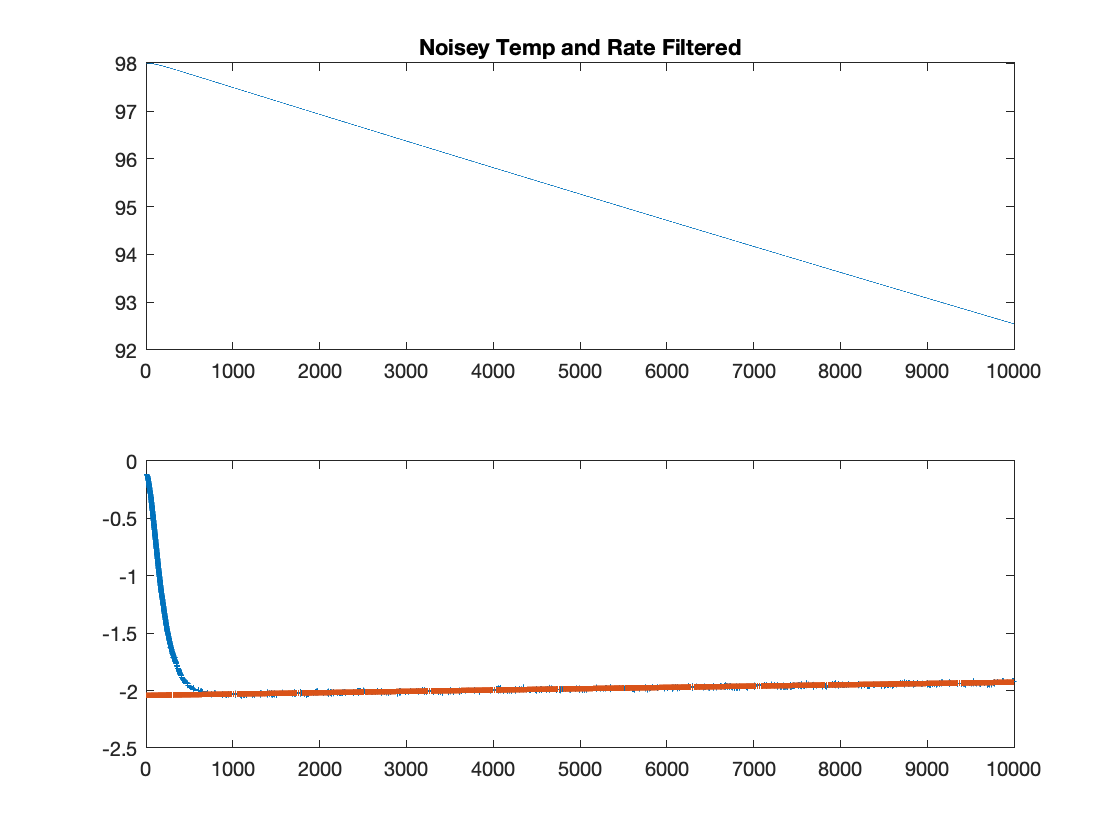



figure
subplot 211
plot(t, HFiltered)
title('Noisey Temp and Rate Filtered')
subplot 212
plot(t(1:end-1), 3600*dHFiltered, 'LineWidth', 3)
hold on
plot(t, 3600*hp(t), 'LineWidth', 3)